# **MATLAB Tutorials**

## **Signal Processing with MATLAB**

Copyright (C) 2005 by Dimitris Manolakis

### **Discrete-Time Signals and Systems**

- **Signal generation and plotting**

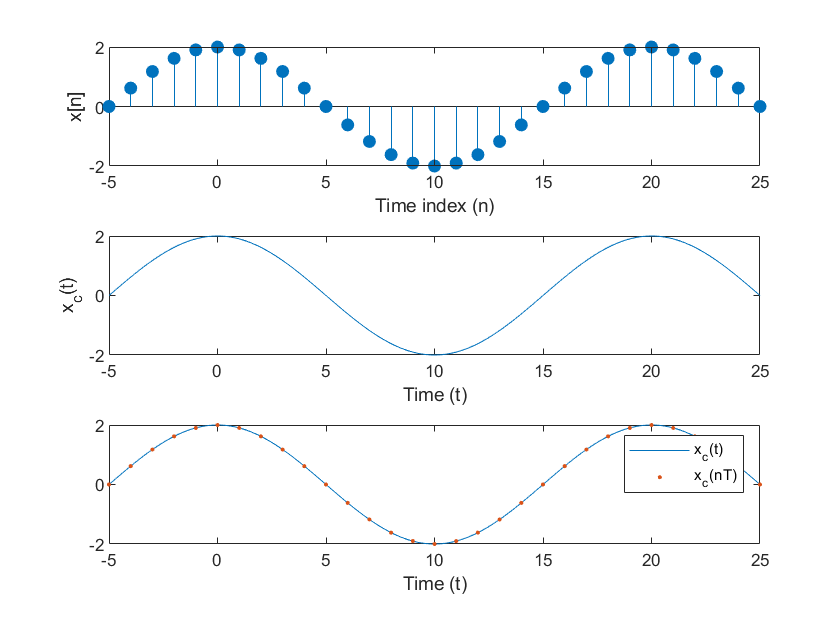

close all; clear;
figure
n=(-5:25);
x=2*cos(2*pi*0.05*n);

subplot(3,1,1);
stem(n,x,'fill');
ylabel('x[n]');
xlabel('Time index (n)');

t=linspace(-5,25,1000);
xc=2*cos(2*pi*0.05*t);

subplot(3,1,2);
plot(t,xc);
ylabel('x_c(t)');
xlabel('Time (t)');

subplot(3,1,3);
plot(t,xc,n,x,'.');
xlabel('Time (t)');
legend('x_c(t)','x_c(nT)')

- **Generate and plot elementary signals**

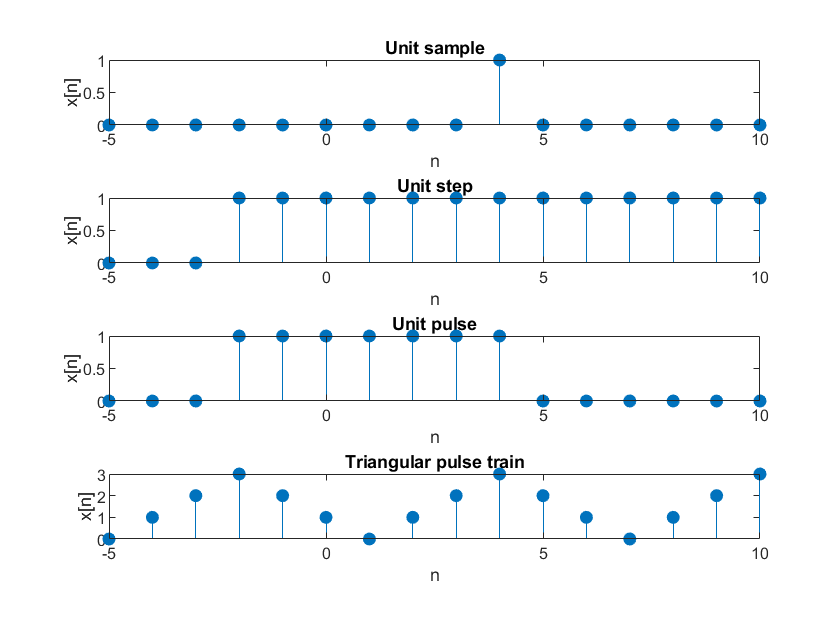

figure
[x,n]=delta(-5,4,10);
subplot(4,1,1), stem(n,x,'fill');
title('Unit sample');
xlabel('n'); ylabel('x[n]');

[x,n]=unitstep(-5,-2,10);
subplot(4,1,2), stem(n,x,'fill');
title('Unit step');
xlabel('n'); ylabel('x[n]');

[x,n]=unitpulse(-5,-2,4,10);
subplot(4,1,3), stem(n,x,'fill');
title('Unit pulse');
xlabel('n'); ylabel('x[n]');

[x,n]=persegen([0 1 2 3 2 1],6,16,-5);
subplot(4,1,4), stem(n,x,'fill');
title('Triangular pulse train');
xlabel('n'); ylabel('x[n]');

- **Time aligment of sequences**

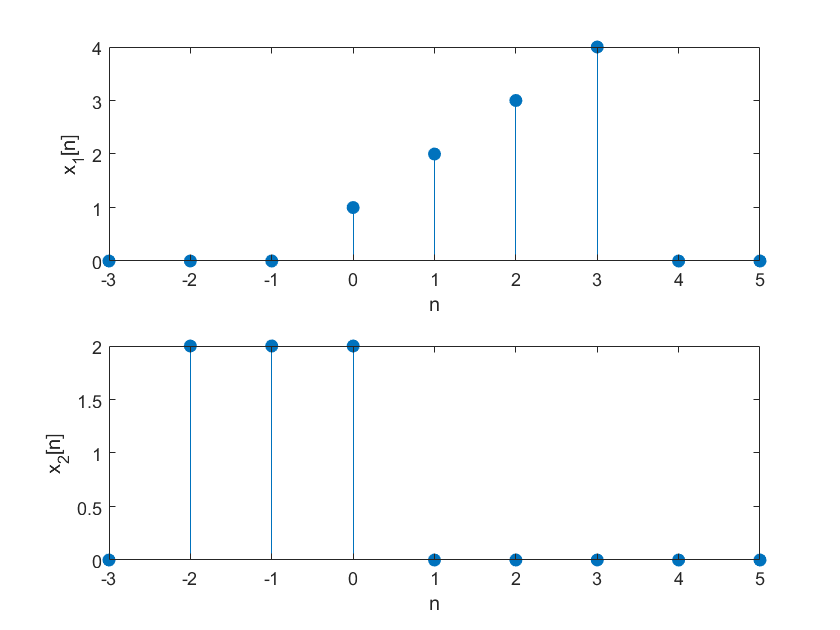

x1=[1 2 3 4 0 0];
n1=[0 1 2 3 4 5];

x2=[0 2 2 2];
n2=[-3 -2 -1 0];

figure
[y1,y2,n]=timealign(x1,n1,x2,n2);
subplot(2,1,1), stem(n,y1,'fill');
xlabel('n'); ylabel('x_1[n]');
subplot(2,1,2), stem(n,y2,'fill');
xlabel('n'); ylabel('x_2[n]');

- **Time reversal and shifting (See Figures 2.9 and 2.10 in textbook)**

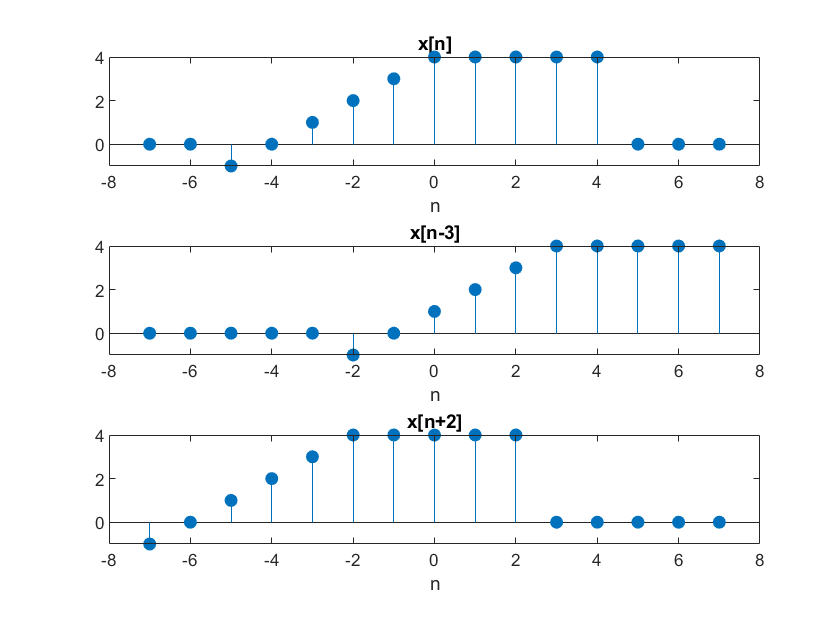

figure

x=[-1 0 1 2 3 4 4 4 4 4];
nx=[-5 -4 -3 -2 -1 0 1 2 3 4];

[x1, n1]=shift(x,nx,-3);
[x2, n2]=shift(x,nx,2);

[y1,y2,n]=timealign(x1,n1,x2,n2);
[y,y1,n]=timealign(x,nx,y1,n);

subplot(3,1,1), stem(n,y,'fill');
title('x[n]'); xlabel('n');
subplot(3,1,2), stem(n,y1,'fill');
title('x[n-3]'); xlabel('n');
subplot(3,1,3), stem(n,y2,'fill');
title('x[n+2]'); xlabel('n');

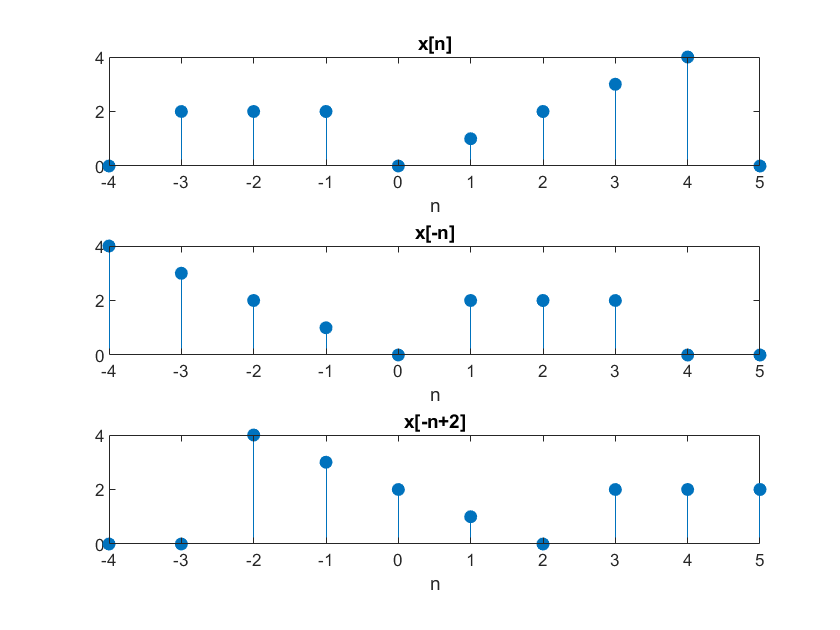


x=[2 2 2 0 1 2 3 4];
nx=[-3 -2 -1 0 1 2 3 4];

[x1, n1]=fold(x,nx);
[x2, n2]=shift(x1,n1,-2);


[y,y1,nt]=timealign(x,nx,x1,n1);
[y,y2,n]=timealign(y,nt,x2,n2);
[y1,y2,n]=timealign(y1,nt,x2,n2);

figure
subplot(3,1,1), stem(n,y,'fill');
title('x[n]'); xlabel('n');
subplot(3,1,2), stem(n,y1,'fill');
title('x[-n]'); xlabel('n');
subplot(3,1,3), stem(n,y2,'fill');
title('x[-n+2]'); xlabel('n');

- **Downsampling: y[n]=x[2n] (See Figure)**

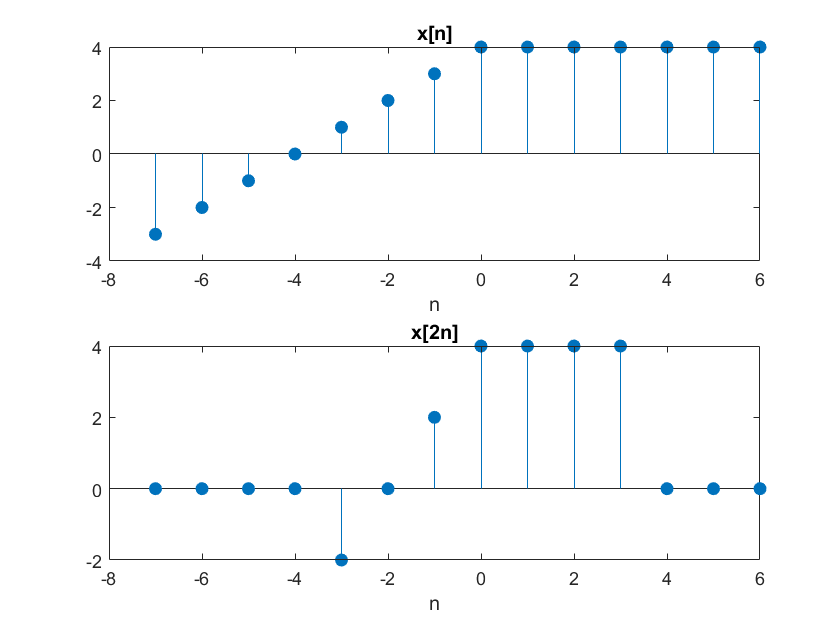

x=[-3 -2 -1 0 1 2 3 4 4 4 4 4 4 4];
nx=(-7:6);

N=length(x);
y=x(2:2:N);
ny=nx(2:2:N)/2;

[x1,y1,n]=timealign(x,nx,y,ny);

figure
subplot(2,1,1), stem(n,x1,'fill');
title('x[n]'); xlabel('n');
subplot(2,1,2), stem(n,y1,'fill');
title('x[2n]'); xlabel('n');

- **Example of DTFT of a complex exponential pulse**

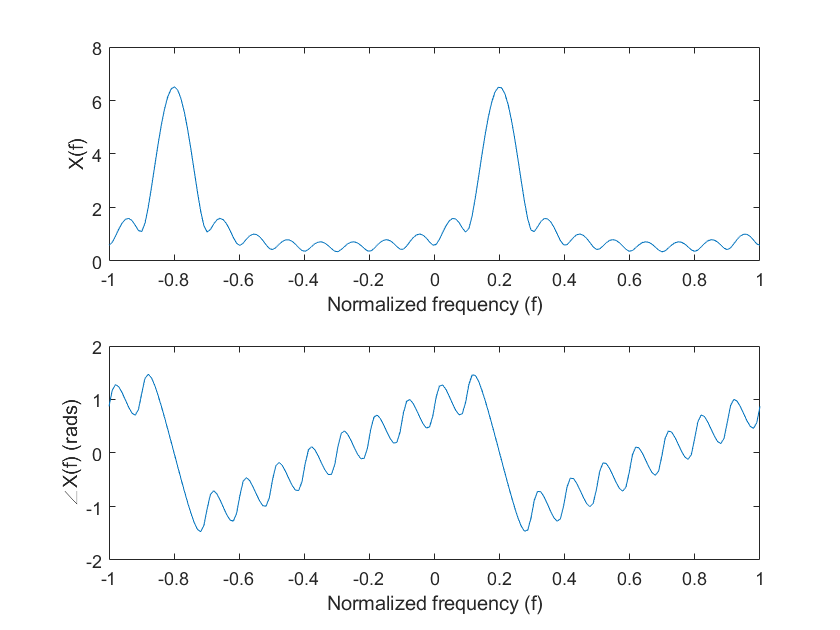

N=10;
n=(0:N-1);
x=(0.9*exp(j*2*pi/5)).^n;
om=linspace(-2*pi,2*pi,200);
X=freqz(x,1,om);
f=om/(2*pi);

figure
subplot(2,1,1),  plot(f,abs(X));
ylabel('X(f)')
xlabel('Normalized frequency (f)');
subplot(2,1,2),  plot(f,angle(X));
ylabel('\angleX(f) (rads)')
xlabel('Normalized frequency (f)');

- **Example of DTFT of a real pulse**

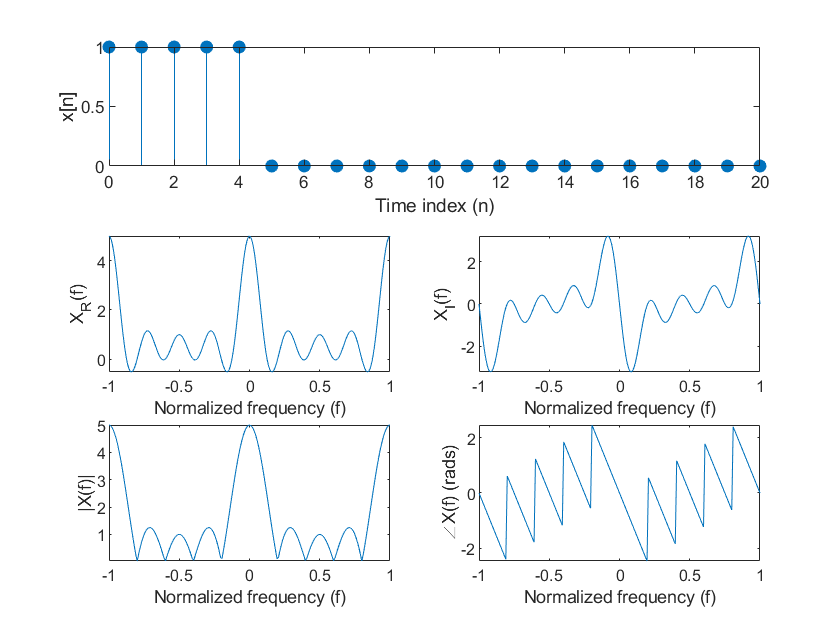

N=10;L=2;
[x,n]=unitpulse(0,0,2*L,2*N);
om=linspace(-2*pi,2*pi,200);
X=freqz(x,1,om); 
f=om/(2*pi);

figure
subplot(3,1,1),  stem(n,x,'fill');
ylabel('x[n]');xlabel('Time index (n)');
subplot(3,2,3),  plot(f,real(X)); axis tight
ylabel('X_R(f)')
xlabel('Normalized frequency (f)');
subplot(3,2,4),  plot(f,imag(X)); 
ylabel('X_I(f)')
xlabel('Normalized frequency (f)');
subplot(3,2,5),  plot(f,abs(X)); axis tight
ylabel('|X(f)|')
xlabel('Normalized frequency (f)');
subplot(3,2,6),  plot(f,angle(X)); 
ylabel('\angleX(f) (rads)')
xlabel('Normalized frequency (f)');

- **Example of DTFT of a real even sequence**

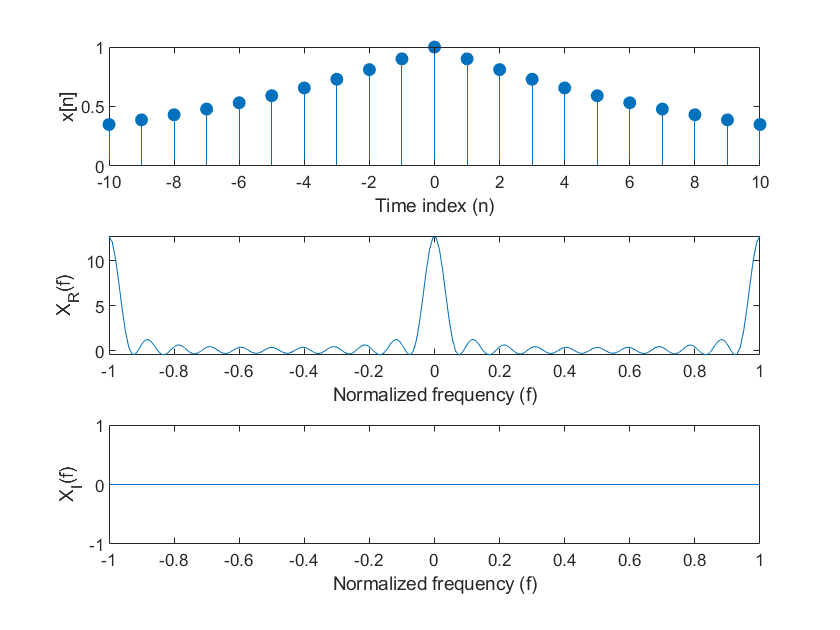

N=10;
n=(-N:N);
x=0.9.^abs(n);
om=linspace(-2*pi,2*pi,200);
X=dtft12(x,-N,om);
f=om/(2*pi);

figure
subplot(3,1,1),  stem(n,x,'fill');
ylabel('x[n]');xlabel('Time index (n)');
subplot(3,1,2),  plot(f,real(X));axis tight;
ylabel('X_R(f)')
xlabel('Normalized frequency (f)');
subplot(3,1,3),  plot(f,imag(X));axis([-Inf Inf -1 1]);
ylabel('X_I(f)')
xlabel('Normalized frequency (f)');

- **Example of DTFT of a real odd sequence**

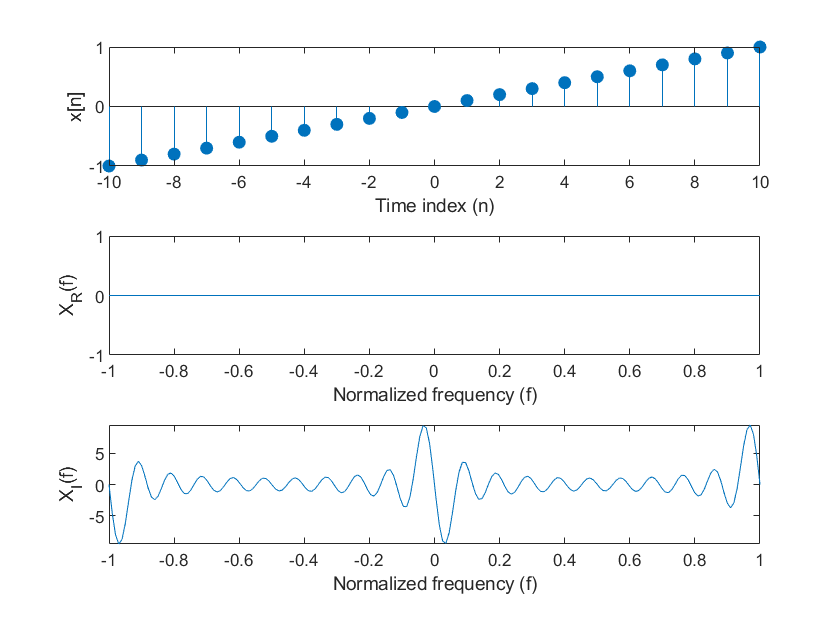

N=10;
n=(-N:N);
x=n/N;
om=linspace(-2*pi,2*pi,200);
X=dtft12(x,-N,om);
f=om/(2*pi);

figure
subplot(3,1,1),  stem(n,x,'fill');
ylabel('x[n]');xlabel('Time index (n)');
subplot(3,1,2),  plot(f,real(X));axis([-Inf Inf -1 1]);
ylabel('X_R(f)')
xlabel('Normalized frequency (f)');
subplot(3,1,3),  plot(f,imag(X));axis tight;
ylabel('X_I(f)')
xlabel('Normalized frequency (f)');

- **Example of DTFT of a real even pulse**

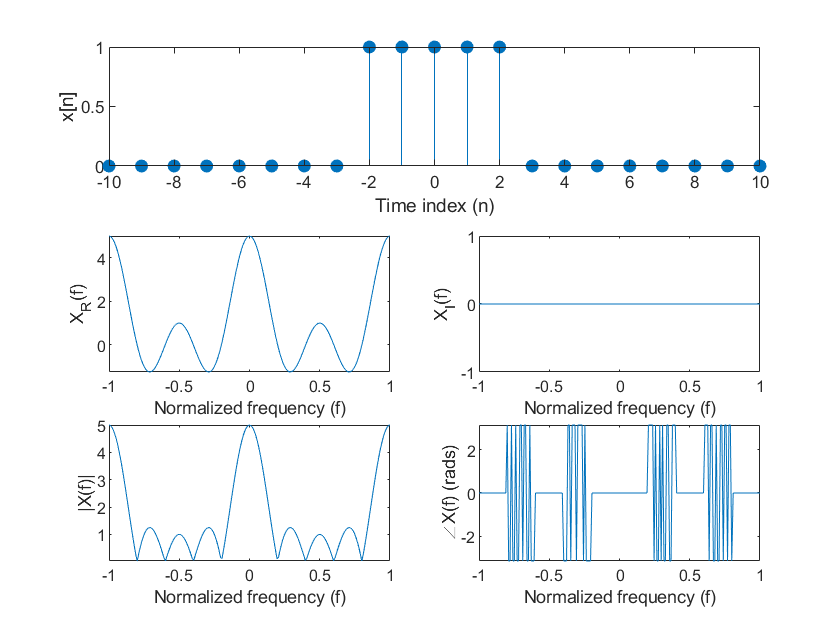

N=10;L=2;
[x,n]=unitpulse(-N,-L,L,N);
om=linspace(-2*pi,2*pi,200);
%X=freqz(x,1,om); % Provides wrong result!
X=dtft12(x,-N,om);
f=om/(2*pi);

figure
subplot(3,1,1),  stem(n,x,'fill');
ylabel('x[n]');xlabel('Time index (n)');
subplot(3,2,3),  plot(f,real(X)); axis tight
ylabel('X_R(f)')
xlabel('Normalized frequency (f)');
subplot(3,2,4),  plot(f,imag(X)); 
axis([-1 1 -1 1]);
ylabel('X_I(f)')
xlabel('Normalized frequency (f)');
subplot(3,2,5),  plot(f,abs(X)); axis tight
ylabel('|X(f)|')
xlabel('Normalized frequency (f)');
subplot(3,2,6),  plot(f,angle(X)); 
ylabel('\angleX(f) (rads)')
xlabel('Normalized frequency (f)');

- **Illustration of frequency shifting theorem**

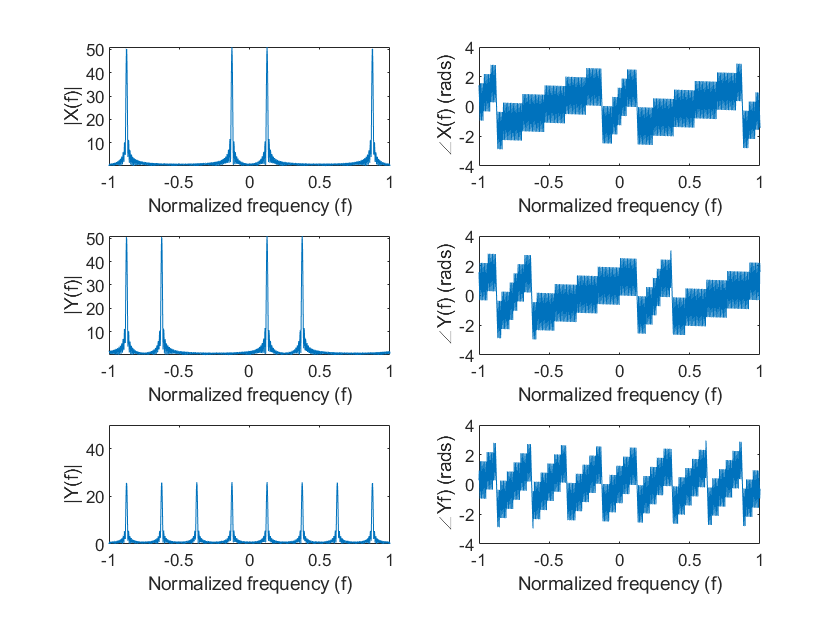

n=(0:100); om0=pi/4; x=cos(om0*n);
omc=pi/2; c1=exp(j*omc*n); y1=c1.*x;
c2=cos(omc*n); y2=c2.*x;

% Compute and plot DTFTs
om=linspace(-2*pi,2*pi,1000);
X=freqz(x,1,om);
Y1=freqz(y1,1,om);
Y2=freqz(y2,1,om);
f=om/(2*pi);

figure
subplot(3,2,1),  plot(f,abs(X)); axis tight
ylabel('|X(f)|')
xlabel('Normalized frequency (f)');
subplot(3,2,2),  plot(f,angle(X)); axis([-1 1 -4 4]);
ylabel('\angleX(f) (rads)');
xlabel('Normalized frequency (f)');
subplot(3,2,3),  plot(f,abs(Y1)); axis tight
ylabel('|Y(f)|')
xlabel('Normalized frequency (f)');
subplot(3,2,4),  plot(f,angle(Y1)); axis([-1 1 -4 4]);
ylabel('\angleY(f) (rads)');
xlabel('Normalized frequency (f)');
subplot(3,2,5),  plot(f,abs(Y2)); axis([-1 1 0 50]);
ylabel('|Y(f)|')
xlabel('Normalized frequency (f)');
subplot(3,2,6),  plot(f,angle(Y2)); axis([-1 1 -4 4]);
ylabel('\angleYf) (rads)');
xlabel('Normalized frequency (f)');

- **Illustration of some DTFT properties (Time reversal property)**

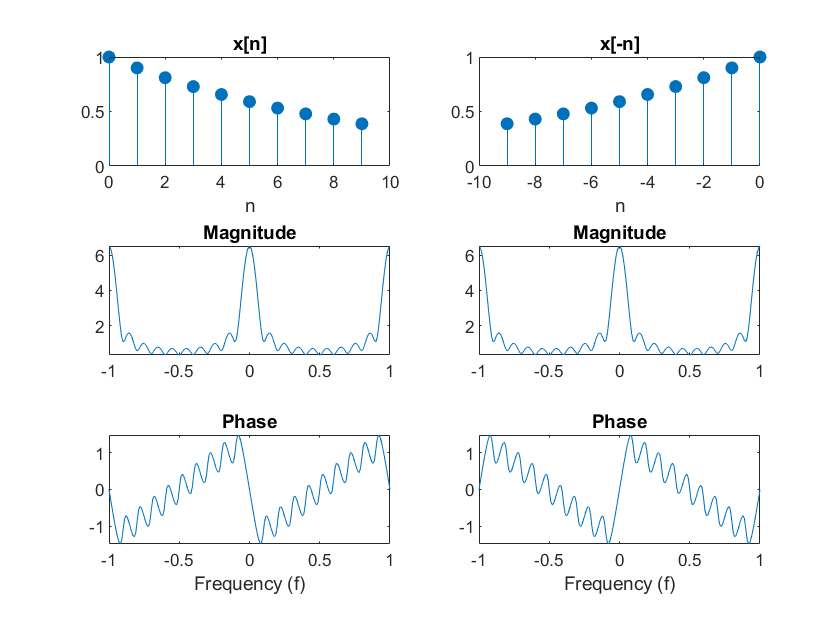

n=(0:9);
x=0.9.^n;
om=linspace(-2*pi,2*pi,200);
X=freqz(x,1,om);
[y,ny]=fold(x,n); 

Y=dtft12(y,ny(1),om);

f=om/(2*pi);

figure
subplot(3,2,1),  stem(n,x,'fill'); xlabel('n');
title('x[n]');
subplot(3,2,3),  plot(f,abs(X));axis tight;
title('Magnitude');
subplot(3,2,5),  plot(f,angle(X));axis tight;
title('Phase');
xlabel('Frequency (f)');
subplot(3,2,2),  stem(ny,y,'fill'); xlabel('n');
title('x[-n]');
subplot(3,2,4),  plot(f,abs(Y));axis tight;
title('Magnitude');
subplot(3,2,6),  plot(f,angle(Y));axis tight;
title('Phase');
xlabel('Frequency (f)');

- **Illustration of some DTFT properties (Time shifting property)**

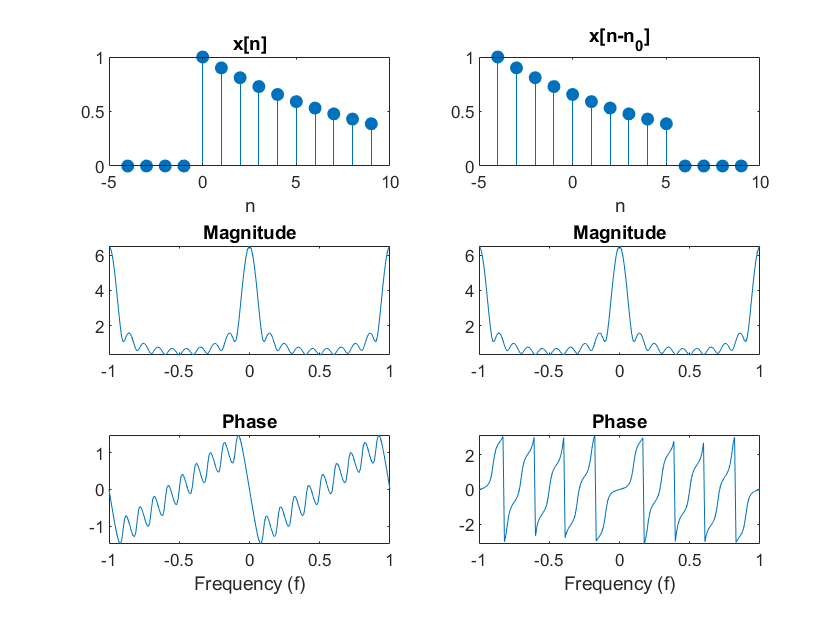

n=(0:9);
x=0.9.^n;
om=linspace(-2*pi,2*pi,200);
X=freqz(x,1,om);
[y,ny]=shift(x,n,4); 
Y=dtft12(y,ny(1),om);
[x1,y1,n12]=timealign(x,n,y,ny);
f=om/(2*pi);

figure
subplot(3,2,1),  stem(n12,x1,'fill'); xlabel('n');
title('x[n]'); 
subplot(3,2,3),  plot(f,abs(X));axis tight;
title('Magnitude');
subplot(3,2,5),  plot(f,angle(X));axis tight;
title('Phase');
xlabel('Frequency (f)');
subplot(3,2,2),  stem(n12,y1,'fill'); xlabel('n');
title('x[n-n_0]');
subplot(3,2,4),  plot(f,abs(Y));axis tight;
title('Magnitude');
subplot(3,2,6),  plot(f,angle(Y));axis tight;
title('Phase');
xlabel('Frequency (f)');